clear; close all; clc;

% addpath("C:\Users\wnd02\source\repos\DCSP\DCSP_Motor\DCSP_Motor_Mov\");

% =========================== DATA Load ==========================
addpath("C:\Users\wnd02\Downloads\gimbal_Gyro_modeling\");
FileLength = 12;
Fs = 0.1;
FreqStart = 0.1;
DATA = cell(FileLength,1);

for k = 1:FileLength
    FileName = sprintf("chan_modeling_%.4fHz_data.out", (k-1)*Fs + FreqStart);
    DATA{k} = load(FileName);
end

DEAD = 2.51;
N_VOL = length(DATA{1});

% fitting Function
Vcmd1 = [0.0, 5-DEAD];
W1 = [-1300, -40];
Vc_W1 = fit(Vcmd1', W1', 'poly1');

Vcmd2 = [DEAD, 5];
W2 = [40, 1300];
Vc_W2 = fit(Vcmd2', W2', 'poly1');

% ================== acquishing estimate coefficient ======================
% initialize 
Vout0 = 0.0;
InValidN = 400;
eMag = zeros(FileLength+1,1); % +1
ePhs = zeros(FileLength+1,1); % +1
eBias = zeros(FileLength,1);
eVout = zeros(N_VOL- InValidN,FileLength);
Vin = zeros(N_VOL - InValidN,FileLength);
freq = zeros(FileLength+1,1);   % +1
x0 = [300, 0, Vout0];
Gm = zeros(FileLength+1, 1);  % +1
mag_in = zeros(FileLength, 1);

% Main loop
for i = 1: FileLength
    time = DATA{i}(InValidN:N_VOL-1,1);
    V_in = DATA{i}(InValidN:N_VOL-1,2);
    W    = DATA{i}(InValidN:N_VOL-1,3);
    freq(i+1) = (i-1)*Fs + FreqStart;
    SysResp = @(x, t) x(1) * cos(2*pi*freq(i+1)*t + x(2)) + x(3);
    
    x = lsqcurvefit(SysResp, x0, time, W);

    eMag(i+1) = x(1);
    ePhs(i+1) = x(2);
    eBias(i) = x(3);
    eVout(:, i) = eMag(i+1)*cos(2*pi*freq(i+1)*time+ePhs(i+1))+eBias(i);
    for k = 1:N_VOL-InValidN
        % V_in preprocessing
        if (V_in(k) < (5-DEAD))
            Vin(k, i) = Vc_W1(V_in(k));
        elseif (V_in(k) > DEAD)
            Vin(k, i) = Vc_W2(V_in(k));
        else
            Vin(k, i) = V_in(k);
        end
    end

    mag_in(i) = (max(V_in)-min(V_in))/2;
    Gm(i+1) = eMag(i+1)/mag_in(i);
end


국소 최솟값이 있을 수 있습니다.

제곱합의 초기값 대비 최종 변화가 함수 허용오차의 
값보다 작기 때문에 lsqcurvefit이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다.

제곱합의 초기값 대비 최종 변화가 함수 허용오차의 
값보다 작기 때문에 lsqcurvefit이(가) 중지되었습니다.

<중지 기준 세부 정보>

국소 최솟값이 있을 수 있습니다.

제곱합의 초기값 대비 최종 변화가 


% Estimated 0[Hz] answer
eMag(1) = eMag(2) - (eMag(3)-eMag(2))*0.5;
Gm(1) = Gm(2) - (Gm(3)-Gm(2))/2;

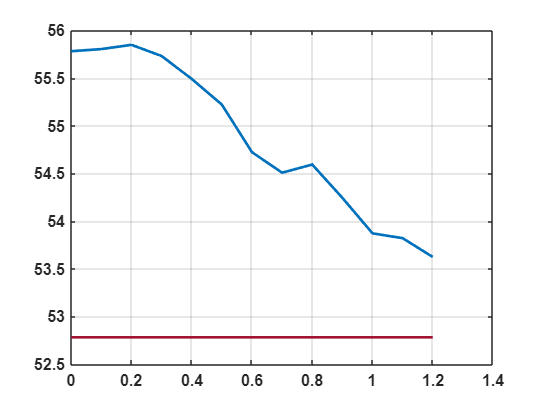

figure; plot(freq, db(Gm), freq, (db(Gm(1))-3)*ones(length(freq)));

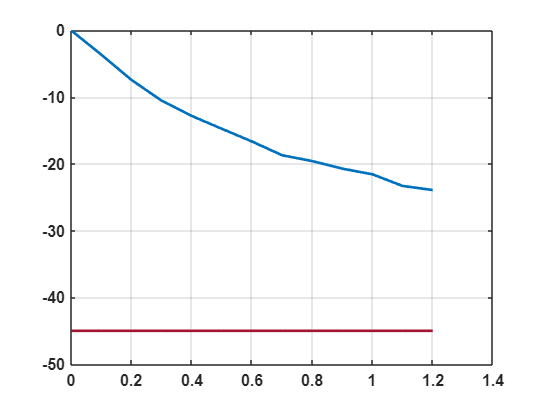

figure; plot(freq, ePhs*180/pi, freq, -45*ones(length(freq)));


tdFreqSys = Gm.*exp(1i*ePhs);
[num, den] = invfreqs(tdFreqSys, freq*2*pi, 1, 2);
[num1, den1] = invfreqs(tdFreqSys, freq*2*pi, 0, 1);

Gp2 = tf(num, den)

Gp2 =
 
  1.137e04 s + 5.346e04
  ---------------------
  s^2 + 27.32 s + 84.84
 
연속시간 전달 함수입니다.



Gp1 = tf(num1, den1)

Gp1 =
 
    7656
  ---------
  s + 13.12
 
연속시간 전달 함수입니다.



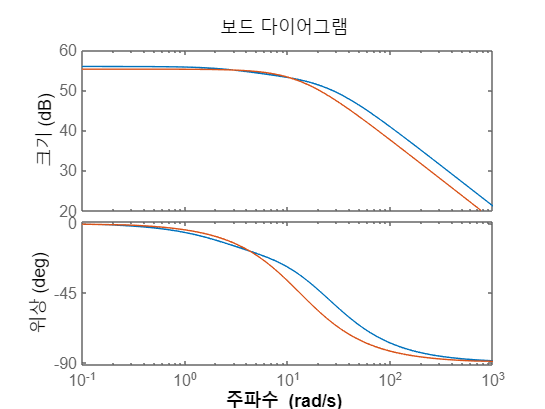


bode(Gp2, Gp1);

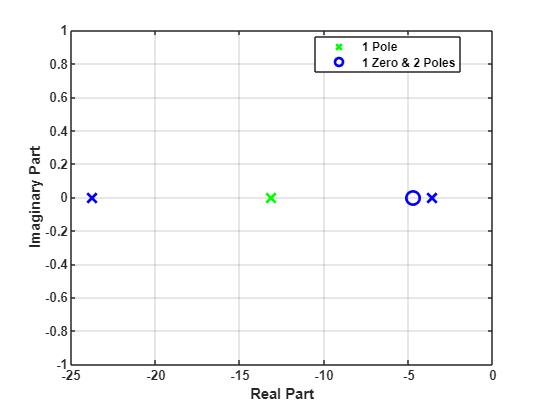

[pole2, zero2] = pzmap(Gp2);
[pole1, zero1] = pzmap(Gp1);

figure;
hold on;
box on;
scatter(real(pole1), imag(pole1), 100, 'g', 'x', 'DisplayName', 'Poles', 'LineWidth', 2); % 극점
scatter(real(zero2), imag(zero2), 100, 'b', 'o', 'DisplayName', 'Zeros', 'LineWidth', 2); % 영점
scatter(real(pole2), imag(pole2), 100, 'b', 'x', 'DisplayName', 'Poles', 'LineWidth', 2); % 극점
hold off;
grid on;    
set(gca, 'FontWeight', 'bold', 'FontSize', 10);
legend ("1 Pole", "1 Zero & 2 Poles", Location = 'best');
xlabel('Real Part');
ylabel('Imaginary Part');

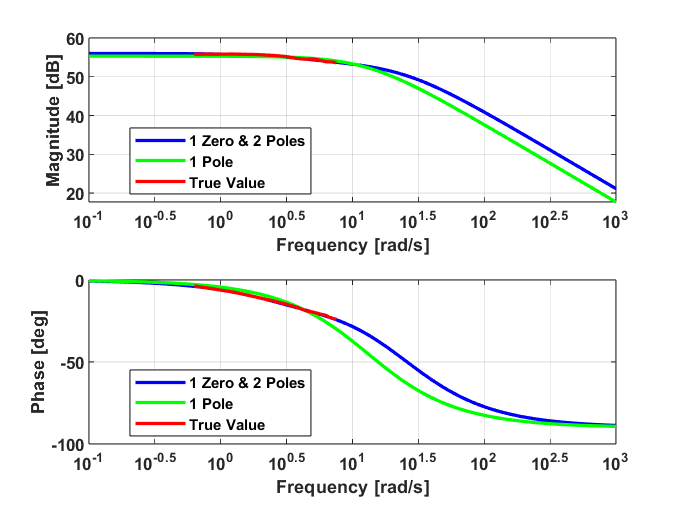


[Mag, Phs, Wout] = bode(Gp2);
[Mag1, Phs1, Wout1] = bode(Gp1);

N = length(Mag);
Mag_plot = squeeze(Mag(1, 1, :));
Phs_plot = squeeze(Phs(1, 1, :));
Mag1 = squeeze(Mag1(1,1,:));
Phs1 = squeeze(Phs1(1,1,:));

figure(); hold on;
subplot(2,1,1); hold on; grid on; box on; 
plot(log10(Wout), db(Mag_plot), 'b', LineWidth = 2); plot(log10(Wout1), db(Mag1), 'g', LineWidth = 2);
plot(log10(freq*2*pi), db(Gm), 'r', LineWidth = 2);
xticklabels({'10^{-1}', '10^{-0.5}', '10^0', '10^{0.5}', '10^1', '10^{1.5}', '10^2', '10^{2.5}', '10^3'}); % 레이블 수동 설정
legend("1 Zero & 2 Poles", "1 Pole", "True Value", Location='best');
xlabel('Frequency [rad/s]', 'Fontsize', 10, 'FontWeight', 'bold'); ylabel("Magnitude [dB]", 'Fontsize', 10, 'FontWeight', 'bold');
set(gca, 'FontWeight', 'bold', 'FontSize', 10);

subplot(2, 1, 2); hold on; grid on; box on; 
plot(log10(Wout), Phs_plot, 'b', LineWidth = 2); plot(log10(Wout1), Phs1, 'g', LineWidth = 2);
plot(log10(freq*2*pi), ePhs*180/pi, 'r', LineWidth = 2);
xticklabels({'10^{-1}', '10^{-0.5}', '10^0', '10^{0.5}', '10^1', '10^{1.5}', '10^2', '10^{2.5}', '10^3'});
legend("1 Zero & 2 Poles", "1 Pole", "True Value", Location='best');
xlabel('Frequency [rad/s]', 'Fontsize', 10, 'FontWeight', 'bold'); ylabel("Phase [deg]", 'Fontsize', 10, 'FontWeight', 'bold'); 
xlim([-1 3]);
ylim([-100 0]);
set(gca, 'FontWeight', 'bold', 'FontSize', 10);

% =============================== Simulation Parameter ===============================
Tstart = 0.0;
Tend = 20.0;
Fs = 200;
Ts = 1/Fs;
addpath("C:\Users\wnd02\OneDrive\바탕 화면\한동 6\디제\MATLAB\simulink\");

% DATA initiation
dataNum = 2;
time_sim = Tstart:Ts:Tend;
freq(dataNum) % display current frequency

ans = 0.1000

func = @(t) 0.5*cos(freq(dataNum)*2*pi*t); % + 2.5;
cosData = func(time_sim);
        

% create Simulation data in
DataIn = [time_sim', cosData'];

[NUM_P, DEN_P] = tfdata(Gp2, 'v');
out = sim('Plant.slx');

[NUM_P, DEN_P] = tfdata(Gp1, 'v');
out2 = sim('Plant.slx');

figure; plot(DATA{dataNum-1}(:,1), DATA{dataNum-1}(:,3), '.b', out.tout, out.Wout,'r',  out2.tout, out2.Wout, 'g', LineWidth = 1.5);
grid on; legend("Raw Data", "Gp_1", "Gp_2");
set(gca, 'Fontsize', 10, 'FontWeight', 'bold');
freq(dataNum)

ans = 0.1000

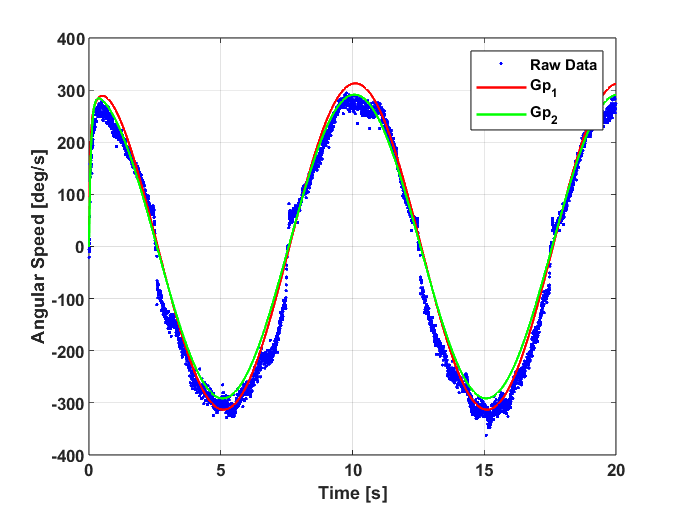

xlabel("Time [s]");
ylabel("Angular Speed [deg/s]");


dataNum = 13;

func = @(t) 0.5*cos(freq(dataNum)*2*pi*t);% + 2.5;
cosData = func(time_sim);
        
% create Simulation data in
DataIn = [time_sim', cosData'];

[NUM_P, DEN_P] = tfdata(Gp2, 'v');
out = sim('Plant.slx');

[NUM_P, DEN_P] = tfdata(Gp1, 'v');
out2 = sim('Plant.slx');


figure; plot(DATA{dataNum-1}(:,1), DATA{dataNum-1}(:,3), '.b', out.tout, out.Wout,'r', out2.tout, out2.Wout, 'g', LineWidth = 1.5);
grid on; legend("Raw Data", "Gp_1", "Gp_2");
set(gca, 'Fontsize', 10, 'FontWeight', 'bold');
freq(dataNum)

ans = 1.2000

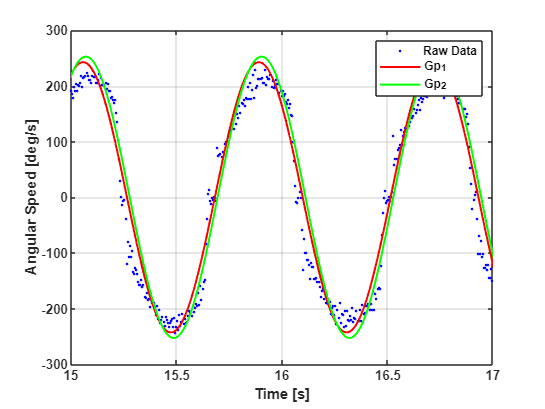

xlabel("Time [s]");
ylabel("Angular Speed [deg/s]");
xlim([15 17]);

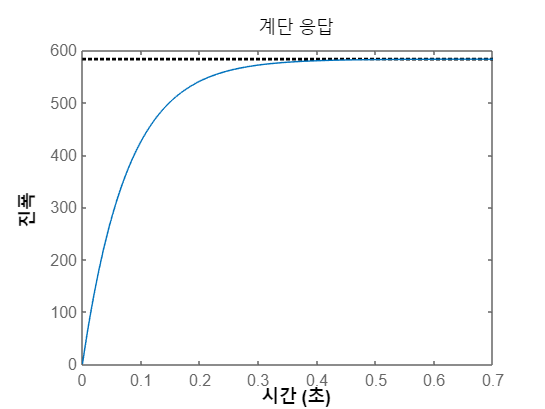


step(Gp1);

[y, tout] = step(Gp2);
maxy = max(y)*0.9;
for k = 1:length(tout)
    if (y(k) > maxy)
        t = tout(k);
        break;
    end
end

t

t = 0.2948